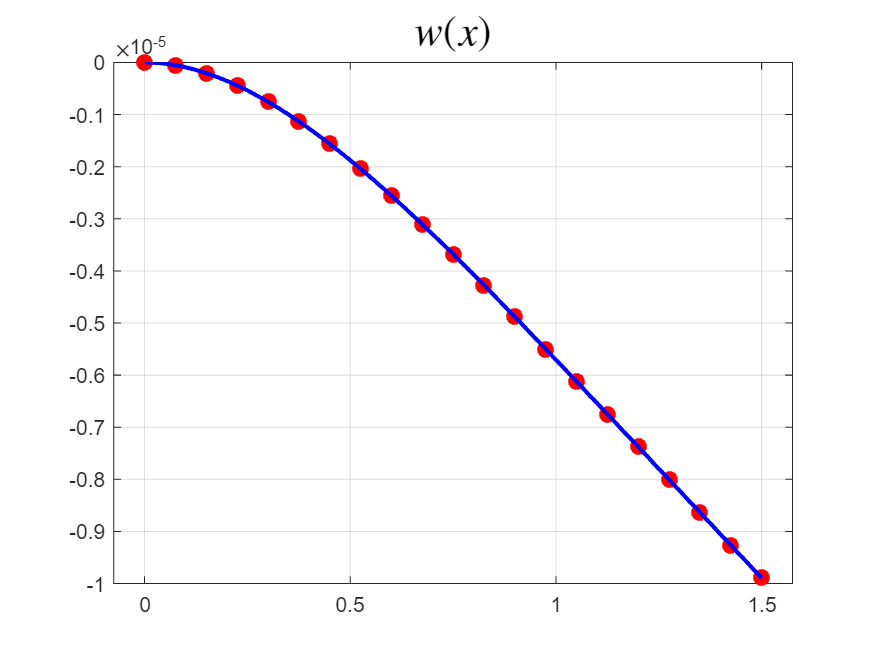

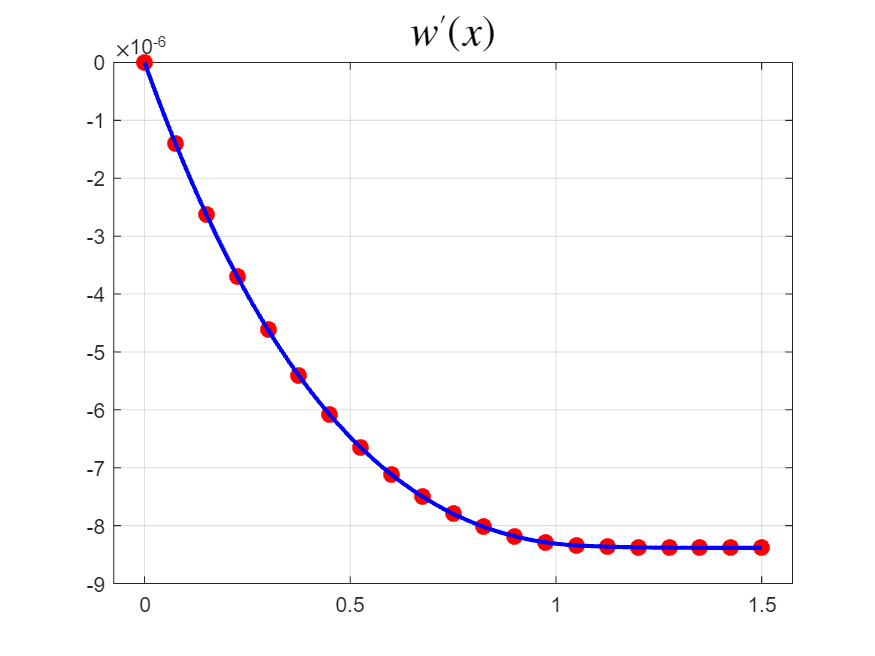

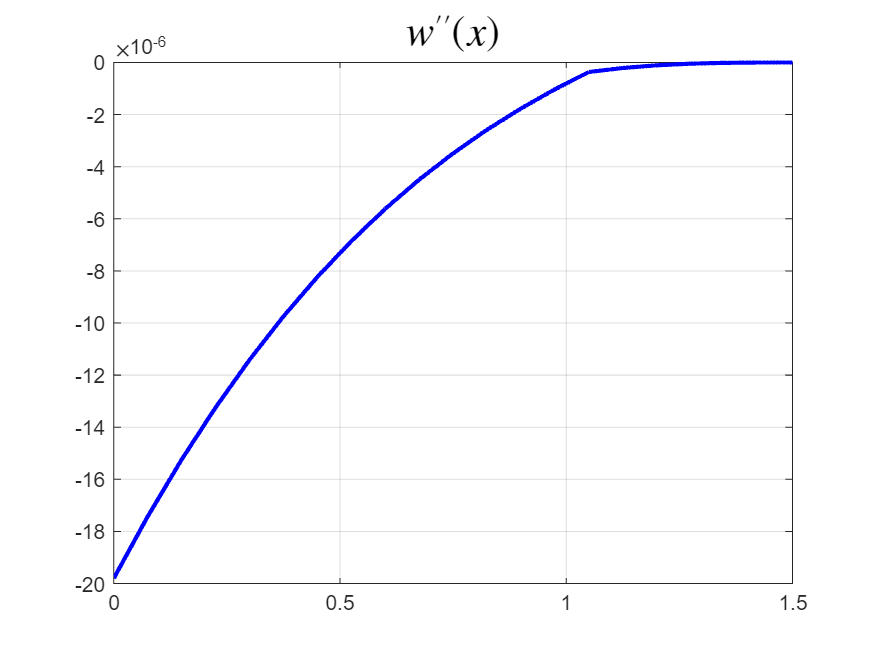

arr = [30];
N = 20;
ptsEL = 25;
b = 50e-3;


EBFlag=true; CIFlag=false; RIFlag=false;
for i =1:length(arr)
    [Delg, x, w, dwdx, d2wdx2]=FEA(N, ptsEL, b*arr(i), EBFlag, CIFlag, RIFlag);
end

function [Delg, x, w, dwdx, d2wdx2] = FEA(N, ptsEL, L, EBFlag, CIFlag, RIFlag)



    %-------  INPUT PARAMETERS --------------
    % in SI units
    E=200e9; 
    b = 50e-3;
    t = 3e-3;
    I= (b^4 - (b-2*t^4 ))/12;
    G=70e9; 
    A=b^2 - (b-2*t)^2; 
    EI=E*I;
    GA=G*A; 
    nu=1/3; 
    Ks=20*(1+nu)/(48+39*nu);
    q0=30e3; % q = q0*(1-x/L)
    F0=5e3; M0=0; 
     
    p=2;

    he=L/N; %Geometric parameter
    w0=0; dwdx0=0; %Essential BCs
    
    TotalDoFs = 2*N*(p-1)+2; %TotalNodes and TotalDoFs
    
    Essential_BC_DoFs = [1, 2];
    Essential_BCs = [w0, dwdx0];

    F0_Loc = 3*L/4;
    F0_element = floor(F0_Loc/he);
    F0_DoF = 2*(F0_element-1) + 1;
    Natural_BC_DoFs = [F0_DoF];
    Natural_BCs = [F0];

    r = length(Essential_BC_DoFs);
    s = length(Natural_BC_DoFs);

    Qg = zeros(TotalDoFs, 1);
    for i=1:s
        DoF = Natural_BC_DoFs(i);
        Qg(DoF) = Natural_BCs(i);
    end

    Delg = zeros(TotalDoFs, 1);
    for i=1:s
        DoF = Essential_BC_DoFs(i);
        Delg(DoF) = Essential_BCs(i);
    end

    %%%%% ASSEMBLY %%%%%%   
    EIe = EI; GAe = GA; cfe = 0;
    Kg = zeros(TotalDoFs);
    fg = zeros(TotalDoFs, 1);

    for e=1:N
        xe = (e-1)*he + he/2; % xe is the position of the element centre
        qe = q0*(1-xe/L);
        
        if(EBFlag==true)
            [Ke, fe] = EM_EB(EIe, cfe, qe, he);
        end

        if(CIFlag == true || RIFlag == true)
            [Ke, fe] = EM_TB(EIe,GAe,Ks,qe,he,CIFlag,RIFlag);
        end
        for i=1:2*p
            I = 2*(e-1)*(p-1)+i;
            fg(I) = fg(I) + fe(i);
            for j=1:2*p
                J = 2*(e-1)*(p-1)+j;
                Kg(I, J) = Kg(I, J) +  Ke(i, j);
            end
        end
    end
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    %%%%% CONDENSATION %%%%%
    Kc = Kg; fc = fg - Kg*Delg; Qc = Qg; DelcRows = 1:TotalDoFs;
    Kc(Essential_BC_DoFs, :) = [];
    Kc(:, Essential_BC_DoFs) = [];
    fc(Essential_BC_DoFs) = [];
    Qc(Essential_BC_DoFs) = [];
    DelcRows(Essential_BC_DoFs) = [];
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    %%%%%% Solving the matrix Equation %%%%%%
    Delc = linsolve(Kc, Qc+fc);

    for i=1:(TotalDoFs-r)
        Delg(DelcRows(i)) = Delc(i);
    end
    Qc = Kg*Delg - fg;
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%% VISUALIZATION %%%%%%
    [x, w, dwdx, d2wdx2] = wSol(Delg,N,he,ptsEL,q0,GAe,Ks,EBFlag,CIFlag,RIFlag);
    % subplot(3, 1, 1);
figure;
    xVec = linspace(0, L, TotalDoFs/2);
    plot(xVec, Delg(1:2:TotalDoFs), ".", MarkerSize=24, Color="red")
    xlim([0-he, L+he]);
    title("$w(x)$", Interpreter="latex", FontSize=20);
    hold on; grid on;
    plot(x, w, LineWidth=2, Color="blue");


  % subplot(3, 1, 2);
  figure;
    plot(xVec, -Delg(2:2:TotalDoFs), ".", MarkerSize=24, Color="red")
    xlim([0-he, L+he]);
    title("$w'(x)$", Interpreter="latex", FontSize=20);
    hold on; grid on;
    plot(x, dwdx, LineWidth=2, Color="blue");



  % subplot(3, 1, 3);
  if(EBFlag==true)
  figure;
    xlim([0-he, L+he]);
    plot(x, d2wdx2, LineWidth=2, Color="blue");
    title("$w''(x)$", Interpreter="latex", FontSize=20);
    grid on;
  end
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
end

#### Function to find element matrices for EB beam theory

function [Ke, fe] =  EM_EB(EIe, cfe, qe, he)
    T1 = [[6,-3*he,-6,-3*he];[-3*he,2*he^2,3*he,he^2];[-6,3*he,6,3*he];[-3*he,he^2,3*he,2*he^2]];
    T2 = [[156,-22*he,54,13*he];[-22*he,4*he^2,-13*he,-3*he^2]; [54,-13*he,156,22*he]; [13*he,-3*he^2,22*he,4*he^2]] ;
    Ke = 2*EIe/he^3*T1 + cfe*he/420*T2 ;

    T3 = [6; -he; 6; he];
    fe = qe*he/12*T3;
end

#### Function to find element matrices for Timoshenko beam theory

function [Ke, fe] =  EM_TB(EIe,GAe,Ks,qe,he,CIFlag,RIFlag)
    Le = EIe/(GAe*Ks*he^2); Mu0=12*Le; Thetae=1-6*Le; Sige=1+3*Le;

    if(CIFlag==true)
       T1 = [6,-3*he,-6,-3*he;
            -3*he,(1.5+6*Le)*he^2,3*he,(1.5-6*Le)*he^2;
            -6,3*he,6,3*he;
            -3*he,(1.5-6*Le)*he^2,3*he,(1.5+6*Le)*he^2];
        Ke = 2*EIe/(Mu0*he^3)*T1;
    
        qev=qe*he/6*[1; 4; 1];
    
        fHat1 = qev(0,0) + qev(1,0)/2;
        fHat2 = -qev(1,0)*he/8;
        fHat3 = qev(2,0) + qev(1,0)/2;
        fHat4 = qev(1,0)*he/8;
        fe = [fHat1; fHat2; fHat3; fHat4]; 
    end

    if(RIFlag==true)
        alphae=4*EIe/(GAe*Ks);
        T1 = [4,-2*he,-4,-2*he;
              -2*he, he^2+alphae,2*he,he^2-alphae;
              -4,2*he,4,2*he;
              -2*he,he^2-alphae,2*he,he^2+alphae];
        Ke = GAe*Ks/4/he*T1;
        fe=qe*he/2*[1; 0; 1; 0];
    end
end

#### Functions for post-processing

function out = wex_EB(x, xej, Delej)
    p = length(xej);
    he = xej(p) - xej(1);
    xbar = (x-xej(1))/he;

    phi0 = 1-3*xbar.^2+2*xbar.^3;
    phi1 = -he*xbar.*(1-xbar).^2;
    phi2 = 3*xbar.^2-2*xbar.^3;
    phi3 = -he*xbar.*(xbar.^2-xbar);

    phiVec=[phi0,phi1,phi2,phi3];

    out = zeros(length(xbar), 1);
    for i=1:length(xbar)
        out(i) =phiVec(i, :)*Delej;
    end
    
end

function out = dwedx_EB(x, xej, Delej)
    p = length(xej);
    he = xej(p) - xej(1);
    xbar = (x-xej(1))/he;

    dphi0dx = -6*xbar/he+6*xbar.^2/he;
    dphi1dx = -(1-xbar).^2 + xbar.*2.*(1-xbar);
    dphi2dx = 6*xbar/he-6*xbar.^2/he;
    dphi3dx = -(xbar.^2-xbar) -xbar.*(2.*xbar-1);

    dphidxVec=[dphi0dx,dphi1dx,dphi2dx,dphi3dx];  

    out = zeros(length(xbar), 1);
    for i=1:length(xbar)
        out(i) =dphidxVec(i, :)*Delej;
    end
end

function out = d2wedx2_EB(x, xej, Delej)
    p = length(xej);
    he = xej(p) - xej(1);
    xbar = (x-xej(1))/he;

    d2phi0dx2 = -6/he.^2+12*xbar/he.^2;
    d2phi1dx2 = 2*(1-xbar)/he + 2/he - 4*xbar/he;
    d2phi2dx2 = 6/he.^2-12*xbar/he.^2;
    d2phi3dx2 = -(2*xbar/he-1/he) -4*xbar/he + 1/he;

    d2phidx2Vec=[d2phi0dx2,d2phi1dx2,d2phi2dx2,d2phi3dx2]; 

    out = zeros(length(xbar), 1);
    for i=1:length(xbar)
        out(i) = d2phidx2Vec(i, :)*Delej;
    end
end


function [Mat1, Mat2, Mat3, Mat4] = wSol(Delg,N,he,ptsEL,q0,GAe,Ks,EBFlag,CIFlag,RIFlag)
    p=2;
    Mat1 = double.empty;
    Mat2 = Mat1;
    Mat3 = Mat1;
    Mat4 = Mat1;
    
    for e=1:N
        xej = linspace(he*(e-1), he*e, 2);
        Delej = Delg((e-1)*(p-1)*2+1:((e)*(p-1)*2+2));

        x = linspace(xej(1), xej(2), ptsEL)';
        
        if(EBFlag==true)
            w = wex_EB(x, xej, Delej);
            dwdx = dwedx_EB(x,xej,Delej);
            d2wdx2 = d2wedx2_EB(x,xej,Delej);
        end

        if(CIFlag==true)
            xbar=(x-xej(1))/he;

            phi1 = 2.*(xbar-1/2).*(xbar-1);
            phic = -4.*xbar.*(xbar-1);
            phi2 = 2.*xbar.*(xbar-1/2);

            dphi1dx = 1/he*(2.*(xbar-1) + 2.*(xbar-1/2));
            dphicdx = 1/he*(-4.*(xbar-1)-4.*xbar);
            dphi2dx = 1/he*(2.*(xbar-1/2)+2.*xbar);
            
            qe = q0*(1-x/(N*he));
            wc = 6*he/(32*GAe*Ks)*qe*he/6*4 + Delej(1)/2 + Delej(3)/2 + he*(Delej(4)-Delej(2))/8;
            
            w = Delej(1)*phi1 + wc*phic + Delej(3)*phi2;
            dwdx = Delej(1)*dphi1dx + wc*dphicdx + Delej(3)*dphi2dx;
            d2wdx2 = NaN;

            
        end

        if(RIFlag)
            xbar=(x-xej(1))/he;
            
            w = Delej(1) + (Delej(3)-Delej(1))*xbar;
            dwdx = Delej(3)/he; 
            d2wdx2 = NaN;
        end

        Mat1 = [Mat1, x];
        Mat2 = [Mat2, w];
        Mat3 = [Mat3, dwdx];
        Mat4 = [Mat4, d2wdx2];
    end
end